% reconstruct analog signal using Cubic spline interpolation
% discrete signal
fs=5000;
% fs=1000; %
ts=1/fs;
n=-25:25;
nts=n*ts;
x=exp(-1000*abs(n*ts)); %discrete time signal
% analog signal reconstruct
dt=0.0005; %min error at dt=0.0005
t=-0.005:dt:0.005;
%analog signal reconstruct from discrete dignal
xa=spline(nts,x,t); 

%check
error=max(abs(xa-exp(-1000*abs(t))))

error = 0.0023

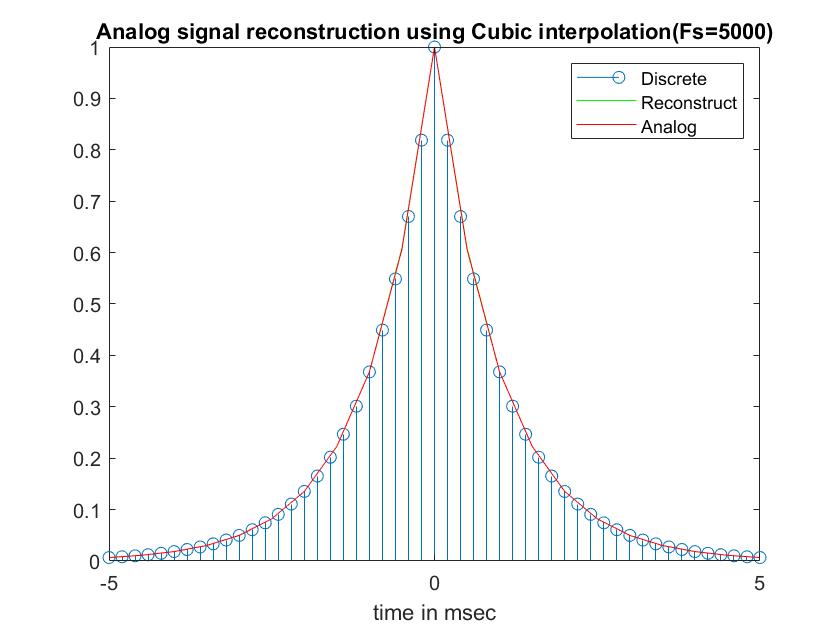

stem(nts*1000,x);hold on
plot(t*1000,xa,'g',t*1000,exp(-1000*abs(t)),'r'); hold off
title(strcat('Analog signal reconstruction using Cubic interpolation(Fs=',num2str(fs),')'))
legend('Discrete','Reconstruct','Analog')
xlabel('time in msec')
xlim([-5 5])